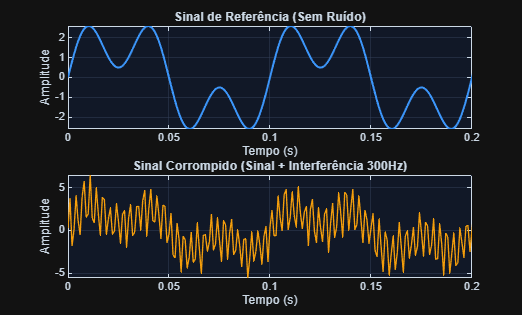

% ==========================================================
% PDS | Digital Signal Processing & Filtering Pipeline
% Target: Noise Reduction via Butterworth Low-Pass Filter
% Language: MATLAB
% ==========================================================

clearvars; close all; clc;

% ----------------------------------------------------------
% Configuração de Tema Escuro (Dark Mode Presets para Web)
% ----------------------------------------------------------
bg_color    = [0.067, 0.094, 0.153]; % Dark Background (#111827)
grid_color  = [0.2, 0.25, 0.35];    % Subtle Grid
text_color  = [0.8, 0.85, 0.9];     % Light Text/Axes

set(0, 'DefaultFigureColor', bg_color);
set(0, 'DefaultAxesColor', bg_color);
set(0, 'DefaultAxesXColor', text_color);
set(0, 'DefaultAxesYColor', text_color);
set(0, 'DefaultAxesGridColor', grid_color);
set(0, 'DefaultAxesGridAlpha', 0.5);
set(0, 'DefaultTextColor', text_color);

% Paleta de Cores de Alto Contraste (RGB Format)
c_blue   = [0.235, 0.588, 0.980]; % #3B82F6 - Sinal Limpo
c_amber  = [0.960, 0.620, 0.043]; % #F59E0B - Sinal Sujo / Ruído
c_emerald = [0.063, 0.804, 0.580]; % #10B981 - Sinal Filtrado

%% 1. Configuração dos Parâmetros e Geração do Sinal
fs = 1000;              % Frequência de amostragem (Hz)
t = 0:1/fs:2;           % Vetor de tempo (2 segundos)

% Componentes Úteis (Sinal Limpo: 10 Hz + 30 Hz)
sinal_limpo = 2 * sin(2*pi*10*t) + 1.5 * sin(2*pi*30*t);

% Componentes de Ruído (EMI 300 Hz + Ruído Estocástico)
ruido = 2.5 * sin(2*pi*300*t) + randn(size(t)) * 0.5;

% Sinal Corrompido
sinal_sujo = sinal_limpo + ruido;

% Plotagem: Sinal no Domínio do Tempo
fig1 = figure('Name', 'Analise Temporal - Entrada');
subplot(2,1,1);
plot(t, sinal_limpo, 'Color', c_blue, 'LineWidth', 1.5);
title('Sinal de Referência (Sem Ruído)'); xlabel('Tempo (s)'); ylabel('Amplitude');
grid on; xlim([0 0.2]);

subplot(2,1,2);
plot(t, sinal_sujo, 'Color', c_amber, 'LineWidth', 1.0);
title('Sinal Corrompido (Sinal + Interferência 300Hz)'); xlabel('Tempo (s)'); ylabel('Amplitude');
grid on; xlim([0 0.2]);

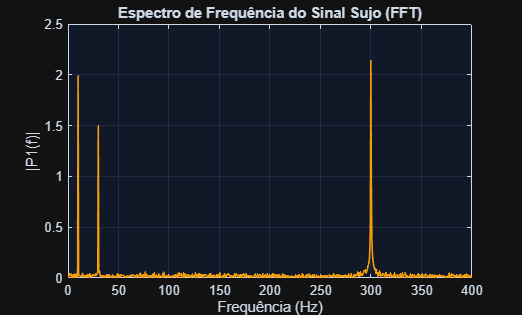


%% 2. Análise de Espectro no Domínio da Frequência (FFT)
N = length(t);
f = (0:N/2) * (fs/N); % Vetor de frequências (Unilateral)

Y_sujo = fft(sinal_sujo);
P2 = abs(Y_sujo/N);
P1 = P2(1:floor(N/2)+1);
P1(2:end-1) = 2*P1(2:end-1);

fig2 = figure('Name', 'Analise Espectral');
plot(f, P1, 'Color', c_amber, 'LineWidth', 1.2);
title('Espectro de Frequência do Sinal Sujo (FFT)');
xlabel('Frequência (Hz)'); ylabel('|P1(f)|');
grid on; xlim([0 400]);

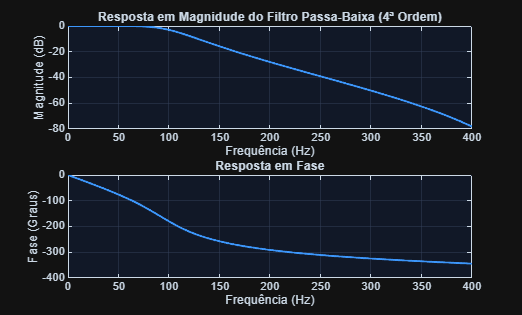


%% 3. Síntese do Filtro IIR Butterworth e Processamento
fc = 100;     % Frequência de corte (100 Hz)
ordem = 4;    % Ordem do filtro

% Síntese dos Coeficientes
[b, a] = butter(ordem, fc/(fs/2), 'low');

% Visualização da Resposta em Frequência
fig3 = figure('Name', 'Resposta do Filtro');
[h, w] = freqz(b, a, 1024, fs);
subplot(2,1,1);
plot(w, 20*log10(abs(h)), 'Color', c_blue, 'LineWidth', 1.5);
title('Resposta em Magnidude do Filtro Passa-Baixa (4ª Ordem)');
xlabel('Frequência (Hz)'); ylabel('Magnitude (dB)'); grid on; xlim([0 400]);

subplot(2,1,2);
plot(w, unwrap(angle(h))*180/pi, 'Color', c_blue, 'LineWidth', 1.5);
title('Resposta em Fase');
xlabel('Frequência (Hz)'); ylabel('Fase (Graus)'); grid on; xlim([0 400]);

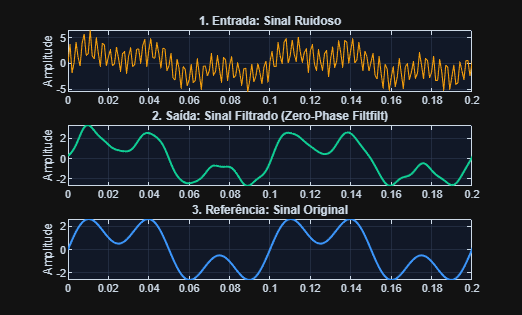


% Filtragem Bidirecional (Fase Zero - Zero-Phase Filtering)
sinal_recuperado = filtfilt(b, a, sinal_sujo);

%% 4. Comparativo Final de Desempenho
fig4 = figure('Name', 'Resultado da Filtragem');
subplot(3,1,1);
plot(t, sinal_sujo, 'Color', c_amber, 'LineWidth', 0.8); 
title('1. Entrada: Sinal Ruidoso'); grid on; xlim([0 0.2]); ylabel('Amplitude');

subplot(3,1,2);
plot(t, sinal_recuperado, 'Color', c_emerald, 'LineWidth', 1.5); 
title('2. Saída: Sinal Filtrado (Zero-Phase Filtfilt)'); grid on; xlim([0 0.2]); ylabel('Amplitude');

subplot(3,1,3);
plot(t, sinal_limpo, 'Color', c_blue, 'LineWidth', 1.5); 
title('3. Referência: Sinal Original'); grid on; xlim([0 0.2]); ylabel('Amplitude');


disp('--> Processamento concluído com sucesso.');

--> Processamento concluído com sucesso.
